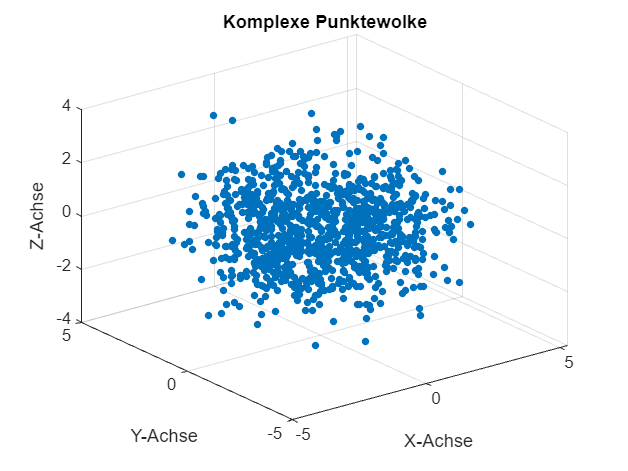

% chrome-extension://efaidnbmnnnibpcajpcglclefindmkaj/https://webmail.rwu.de/SOGo/so/fl-224751/Mail/0/folderINBOX/1128/2/pointcloud_similarity_measures.pdf
% https://github.com/BerensRWU/Point-Cloud-Comparison/blob/main/metrics.py
% https://github.com/pyvista/fast-simplification
% http://ycb-benchmarks.s3-website-us-east-1.amazonaws.com/
% Anzahl der Punkte in der Wolk
numPoints = 1000;

%seed setzen für die random Zahlen, damit diese Vergleichbar bleiben
rng(42);

% Erstellen von zufälligen Punkten in einem begrenzten Bereich
x = randn(1, numPoints);
y = randn(1, numPoints);
z = randn(1, numPoints);

% Füge einige Strukturen oder Muster hinzu, um die Komplexität zu erhöhen
theta = linspace(0, 4 * pi, numPoints);
x = x + 2 * cos(theta);
y = y + 2 * sin(theta);
z = z + 0.5 * randn(1, numPoints);

% Erstelle die komplexe Punktewolke
ptCloud = pointCloud([x', y', z']);

% Visualisiere die Punktewolke
figure;
scatter3(ptCloud.Location(:,1), ptCloud.Location(:,2), ptCloud.Location(:,3), 20, 'filled');
xlabel('X-Achse');
ylabel('Y-Achse');
zlabel('Z-Achse');
title('Komplexe Punktewolke');


% Translation und Rotation
translationVector = [0.1, 0.2, 2];
rotationAngles = [30, 45, 15]; % Rotationswinkel in Grad um die X-, Y-, und Z-Achsen

% Rotationsmatrix
rotationMatrix = eul2rotm(deg2rad(rotationAngles));

% starren 3D-Transformation
transform = rigid3d(rotationMatrix, translationVector);

% Transformiere Punktewolke
ptCloudTransformed = pctransform(ptCloud, transform);

% Rauschen 
numPoints = size(ptCloudTransformed.Location, 1);
noise = noiseFactor * randn(numPoints, 3);
ptCloudNoisy = pointCloud(ptCloudTransformed.Location + noise);

% Downsampling Methode
gridStep = 0.5;
ptCloudDownSampled = pcdownsample(ptCloudNoisy,'gridAverage',gridStep);

% Anzahl der Punkte zählen -> vgl. ob Downsampling durchgeführt wurde
numPointsDownSampled = ptCloudDownSampled.Count;

% Gib die Anzahl der Punkte aus
disp(['Ursprüngliche Punktewolke: ', num2str(numPoints), ' Punkte']);

Ursprüngliche Punktewolke: 1000 Punkte


disp(['Downgesamplete Punktewolke: ', num2str(numPointsDownSampled), ' Punkte']);

Downgesamplete Punktewolke: 717 Punkte


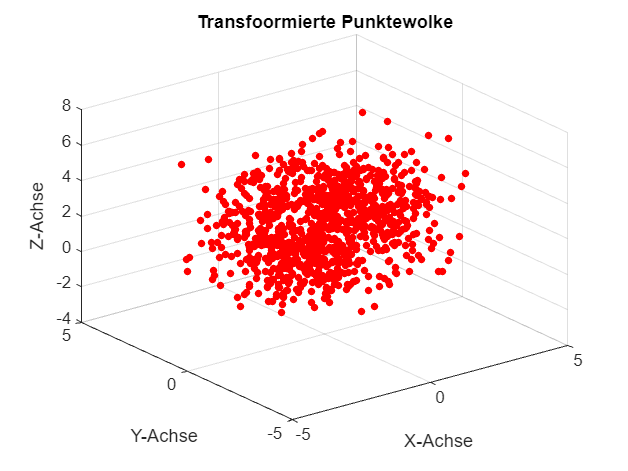


figure;
scatter3(ptCloudNoisy.Location(:,1), ptCloudNoisy.Location(:,2), ptCloudNoisy.Location(:,3), 20, 'filled','r');
xlabel('X-Achse');
ylabel('Y-Achse');
zlabel('Z-Achse');
title('Transfoormierte Punktewolke');


%ICP-Registration and RMSE
[tformEstimated,temp,rmse]= pcregistericp(ptCloudDownSampled,ptCloud);
disp(rmse);

    0.4828

